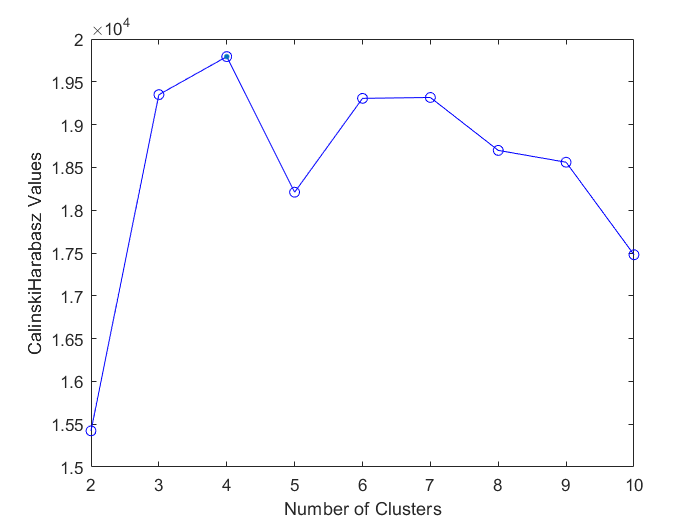

folder = 'E:\gridfitdir.22.03.19';
genNum = 1;
%hpp = {'Sayany', 46, [1.068922; 1071562; 1/15676], ...
%        [11000 12100; 12550 13500; 2700 2800; 21 37; 25 35; 2000 2160; ...
%            28 32; 4 10; 600 650; 0 35; 60 90; 450 530; 4 6]};
hpp = {'Baksan', 40, [0.153324; (34837+4592+258)*(6300/6316)^2; 1/6316], ...
       [2300 2700; 100 500; 725 775; 10 25; 10 16; 900 1050; 10 18; ...
        4 10; 460 490; 0 20; 40 80; 300 350; 4 6]};

fstr = repmat('%f ', 1, 16);
folderPath = fullfile([folder '\populations.' hpp{1} '.750\']);
data = [];
for i = 1 : genNum
    filePath = fullfile([folderPath 'G' num2str(hpp{2}-i) '.' hpp{1} '.750p.txt']);
    fid =  fopen(filePath, 'r');
    datacell = textscan(fid, fstr, 'Delimiter', '\t');
    datacell = cell2mat(datacell);    
    data = [data; datacell];
    fclose all;
end
meas = data(:, 1:13);
species = data(:, 14:16);

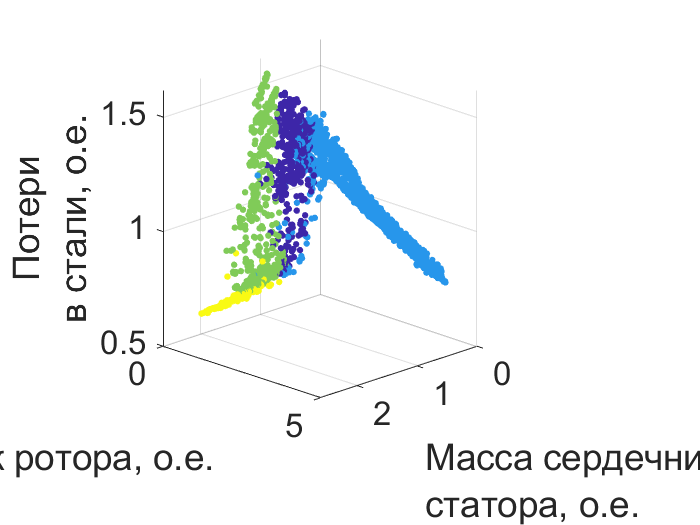

rng('default')
eva = evalclusters(meas, 'kmeans', 'CalinskiHarabasz', 'KList', 1:5);
plot(eva)
%sidx = categorical(flipud(species));

scatter3(species(:,1)/hpp{3}(1), ...
         species(:,3)/hpp{3}(3), ...
         species(:,2)/hpp{3}(2), ...
         15, eva.OptimalY, 'filled')
xlabel({'Масса сердечника';'статора, о.е.'}, 'FontSize', 20)
ylabel('Ток ротора, о.е.', 'FontSize', 20)
zlabel({'Потери'; 'в стали, о.е.'}, 'FontSize', 20)  
view([135 16])
set(gca,'FontSize', 20)

hold off


figure
for i = 1:3
    inc = eva.OptimalY == i;
    grp = meas(inc, :);
    dlt = repmat((lub(:,2)-lub(:,1))', sum(inc), 1);
    drmn = repmat(lub(:,1)', sum(inc), 1);
    rmn = rdivide(grp-drmn, dlt);
    s = stem(rmn');

%plot(rmn', 'LineStyle', 'none', 'Marker', 'o', 'MarkerEdgeColor', [0 0.45 0.74])
%plot(rmn', 'LineStyle', 'none', 'Marker', 'o', 'MarkerEdgeColor', [0.85 0.33 0.1])
nmpr = {'D_g', 'D_y', 'l_1' , 'B_{s2}', 'δ', 'R_p', 'd_d', 'r_{ld}', ...
        'w_{pmn}', 'w_{pmj}', 'h_{ps}', 'b_{p}', 'b_{so}'};
set(gca, 'xtick', [1:length(lub)], 'xticklabel', nmpr, 'FontSize', 15)
set(s, 'Color', [0 0.45 0.74])    % blue
%set(s, 'Color', [0.85 0.33 0.1])   % red
%set(s, 'Color', [0.93 0.69 0.13]) % yellow
%set(s, 'Color', [0.49 0.18 0.56]) % puple
%set(s, 'Color', [0.47 0.67 0.19]) % green
end
%}